# Examples of application of polarPcolor with different options

## Minimalist example

Assuming that a remote sensor is measuring the wind field for a radial distance ranging from 50 to 1000 m. The scanning azimuth is oriented from North (0 deg) to North-North-East ( 80 deg):

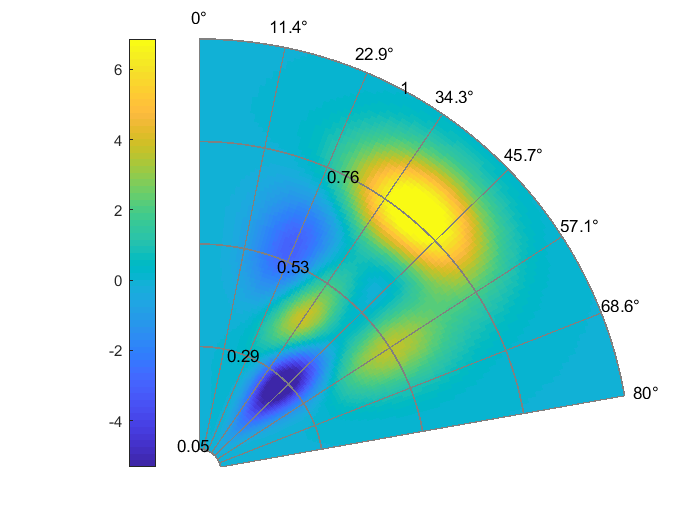

R = linspace(50,1000,100)./1000; % (distance in km)
Az = linspace(0,80,100); % in degrees
[~,~,windSpeed] = peaks(100); % radial wind speed
figure
[h,c]=polarPcolor(R,Az,windSpeed);

## Different number of circles and ticklabel for the radial axis

We want to have 4 circles and 7 spokes, and to give a label to the radial coordinate

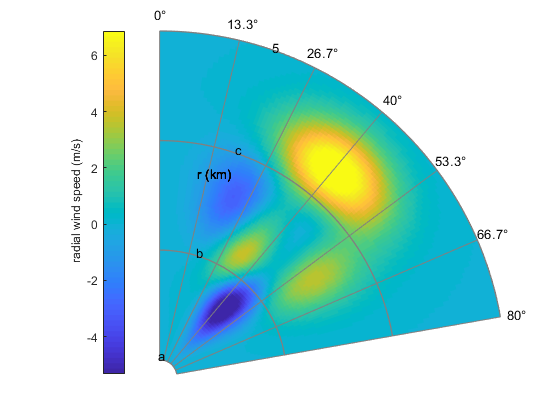

Rticks = {'a','b','c','5'}; % tick label for the radial axis. If defined, it must be a cell array of characters with numel(Ritcks)=Ncircles
Ncircles = 4;
figure
[~,c]=polarPcolor(R,Az,windSpeed,'labelR','r (km)','Ncircles',Ncircles,'Nspokes',7,'Rticklabel',Rticks);
ylabel(c,' radial wind speed (m/s)');
set(gcf,'color','w')

## Dealing with outliers

We introduce outliers in the wind velocity data. These outliers are represented as wind speed sample with a value of 100 m/s. These corresponds to unrealistic data that need to be ignored. To avoid bad scaling of the colorbar, the function polarPcolor uses the function caxis combined to the function quantile to keep the colorbar properly scaled: caxis([quantile(Z(:),0.01),quantile(Z(:),0.99)])

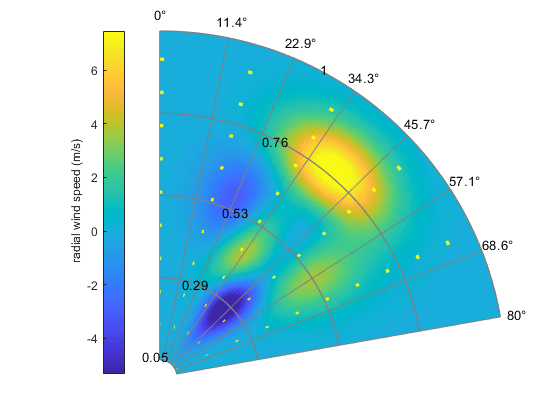


windSpeed(1:10:end,1:20:end)=100;
figure
[~,c]=polarPcolor(R,Az,windSpeed);
ylabel(c,' radial wind speed (m/s)');
set(gcf,'color','w')

## polarPcolor without colorbar

The colorbar is activated by default. It is possible to remove it by using the option 'colBar'. When the colorbar is desactivated, the outliers are not "removed" and bad scaling is clearly visible:

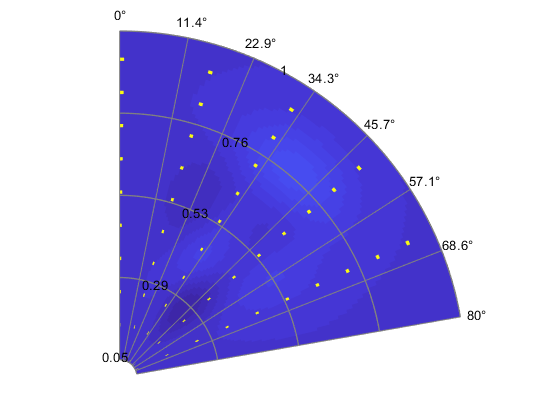

figure
polarPcolor(R,Az,windSpeed,'colBar',0) ;

## Different geometry 1

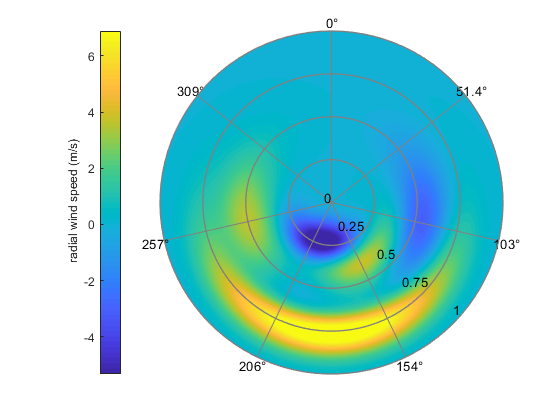

N = 360;
R = linspace(0,1000,N)./1000; % (distance in km)
Az = linspace(0,360,N); % in degrees
[~,~,windSpeed] = peaks(N); % radial wind speed
figure
[~,c]= polarPcolor(R,Az,windSpeed);
ylabel(c,' radial wind speed (m/s)');
set(gcf,'color','w')

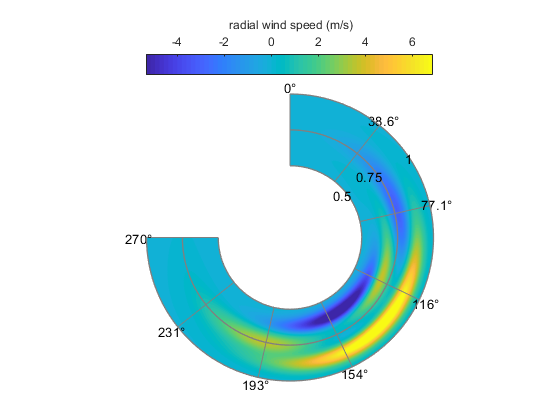

%% Different geometry 2
N = 360;
R = linspace(500,1000,N)./1000; % (distance in km)
Az = linspace(0,270,N); % in degrees
[~,~,windSpeed] = peaks(N); % radial wind speed
figure
[~,c]= polarPcolor(R,Az,windSpeed,'Ncircles',3);
location = 'NorthOutside';
ylabel(c,' radial wind speed (m/s)');
set(c,'location',location);
set(gcf,'color','w')

## Case of logartihmic radial vector

clf;close all;
R = logspace(log10(0.013),log10(1000),100); % radial vector
% R = logspace(-3,1,100); % radial vector
Az = linspace(0,180,200); % in degrees
Z = exp(-0.5*R(:))*cosd(90-2*Az); 
[X,Y] = meshgrid(R,Az);

figure

subplot(221)
hold on; box on
pcolor(X',Y',Z);shading flat;
xlabel('R')
ylabel('\theta (deg)')
grid on
axis tight
set(gca,'layer','top')
title('linear scale')

subplot(222)
pcolor(X',Y',Z);shading flat;
set(gca,'xscale','log')
xlabel('R')
ylabel('\theta (deg)')
grid on
set(gca,'layer','top')
title('semilogx scale')

subplot(223)
polarPcolor(R,Az,Z,'Rscale','linear','Ncircles',5,'Nspokes',5)
caxis([-1,1])
colorbar off
title('linear scale')

subplot(224)
polarPcolor(R,Az,Z,'Rscale','log','Ncircles',5,'Nspokes',5)

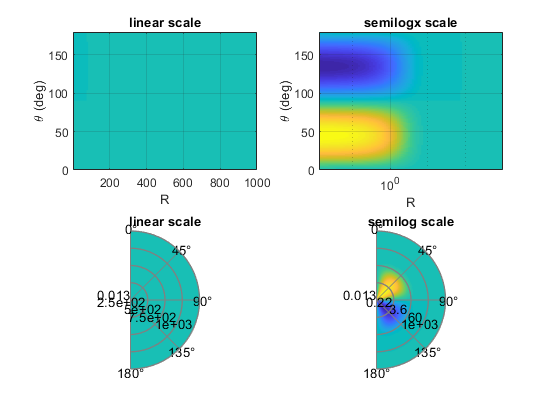

% the warning above is normal (see next section)

caxis([-1,1])
set(gcf,'color','w')
colorbar off
title('semilog scale')

## Choice between origin centered at lowest value of R or at 0

The option 'Origin' can be 'auto' (default) where the radial plot is centered in 0 or "Rmin" where the radial plot is centered on the lowest value of R. Note that this option is not compatible with Rscale = 'log'.

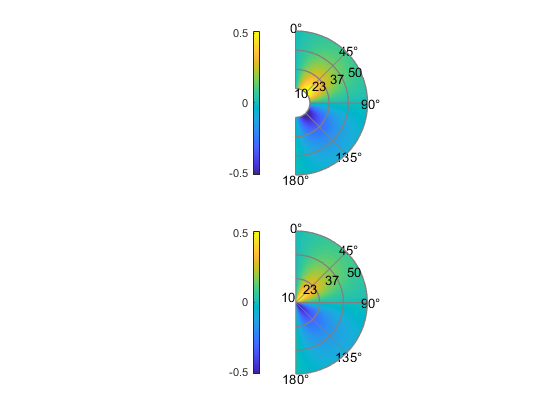

clf;close all;
R = linspace(10,50,100); % radial vector
% R = logspace(-3,1,100); % radial vector
Az = linspace(0,180,200); % in degrees
Z = exp(-0.05*R(:))*cosd(90-2*Az); 
[X,Y] = meshgrid(R,Az);
figure
subplot(211)
polarPcolor(R,Az,Z,'Rscale','lin','Ncircles',4,'Nspokes',5,'Origin','auto'); % default option 
subplot(212)
polarPcolor(R,Az,Z,'Rscale','lin','Ncircles',4,'Nspokes',5,'Origin','Rmin');   % force polar plot to be centered in Rmin